# Force control system - Thesis

Initial clear all set variables

close all
clear all

## Transfer function setting

s = tf('s') % Setting s as transfer variable

s =
 
  s
 
Continuous-time transfer function.




% Given values
K = 0.843121; % Replace with your actual gain
theta = 0.09; % Replace with your actual delay
tau = 0.09;   % Replace with your actual time constant

% Construct the transfer function
numerator = K;
denominator = [tau, 1];

% Create the transfer function
sys = tf(numerator, denominator, 'InputDelay', theta);

G = minreal(tf(numerator,denominator))

G =
 
    9.368
  ---------
  s + 11.11
 
Continuous-time transfer function.



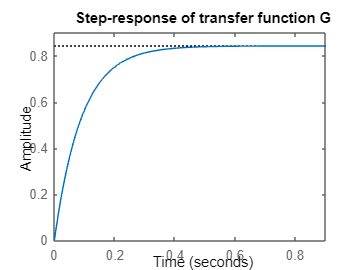

step(G)
title('Step-response of transfer function G')


G2 = (K*exp(-theta*s))/(tau*s+1)

G2 =
 
                   0.8431
  exp(-0.09*s) * ----------
                 0.09 s + 1
 
Continuous-time transfer function.



## Controller Recipe

% Choose parameters

phase_margin = 150; 
Ni = 3; 
alpha = 0.08; 

% Contribution calculations
phi_i = rad2deg(-atan(1/Ni))

phi_i = -18.4349

phi_m = rad2deg(asin((1-alpha)/(1+alpha)))

phi_m = 58.4137


% Damaged phase
Gjwc = phase_margin - phi_i - 180 - phi_m

Gjwc = -69.9787

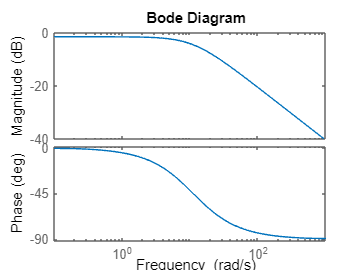

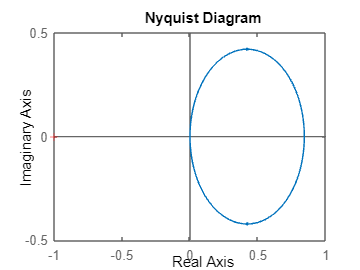

G =
 
    9.368
  ---------
  s + 11.11
 
Continuous-time transfer function.



ans =
 
    187.4
  ---------
  s + 11.11
 
Continuous-time transfer function.



bode(G)


% Calculate crossover frequency from bode intersection of damaged phase
wc = 30;

% Calculate constants
td = 1/(wc*sqrt(alpha))

td = 0.1179

ti = Ni*(1/wc)

ti = 0.1000


% Calculate controllers
Cpi = (ti*s+1)/(ti*s)

Cpi =
 
  0.1 s + 1
  ---------
    0.1 s
 
Continuous-time transfer function.



Cd = 1+td*s;
Clead = (td*s+1)/(alpha*td*s+1)

Clead =
 
   0.1179 s + 1
  --------------
  0.009428 s + 1
 
Continuous-time transfer function.




% Finding Kp we need open loop
G_ol = minreal(Cpi*Clead*G)

G_ol =
 
  117.1 s^2 + 2165 s + 9936
  -------------------------
  s^3 + 117.2 s^2 + 1179 s
 
Continuous-time transfer function.



Kp = 1/abs(freqresp(G_ol,wc*1i))

Kp = 0.9163


Cpi*Clead*Kp

ans =
 
  0.0108 s^2 + 0.1996 s + 0.9163
  ------------------------------
      0.0009428 s^2 + 0.1 s
 
Continuous-time transfer function.



K_D = 12.5000

K_C = 231.0660

K_I = 1.0607e+03

F = 106.0660


% Final closed loop and step resp
G_cl = minreal(Kp*G_ol/(1+Kp*G_ol))

G_cl =
 
     107.3 s^2 + 1984 s + 9105
  -------------------------------
  s^3 + 224.5 s^2 + 3162 s + 9105
 
Continuous-time transfer function.



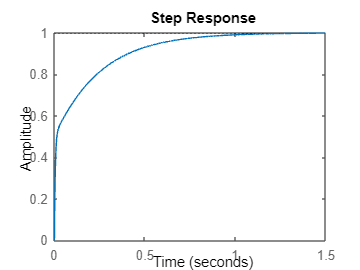

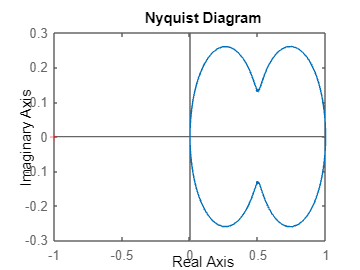

step(G_cl,1.5);

G_ctrl =
 
  11.45 s^2 + 211.7 s + 971.9
  ---------------------------
         s^2 + 106.1 s
 
Continuous-time transfer function.



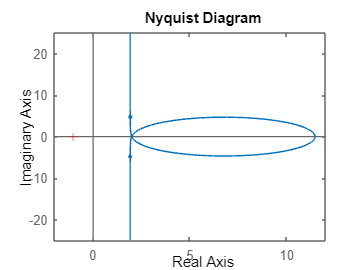

% Controller
G_ctrl = minreal(Kp*Cpi*Clead)


syms s t                                                    % Invoke Symbolic Math Toolbox

num = G_ctrl.Numerator{1};
den = G_ctrl.Denominator{1};

% Filter from continuous to discrete to find alpha and beta
G_filt = tf(1,den(1:2))

G_filt =
 
      1
  ---------
  s + 106.1
 
Continuous-time transfer function.



G_filt_d = c2d(G_filt,0.025)

G_filt_d =
 
   0.008763
  -----------
  z - 0.07053
 
Sample time: 0.025 seconds
Discrete-time transfer function.




ssCtrl = ss(-den(2),1,1,0);
ssCtrl_d = c2d(ssCtrl,0.025)

ssCtrl_d =
 
  A = 
            x1
   x1  0.07053
 
  B = 
             u1
   x1  0.008763
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.025 seconds
Discrete-time state-space model.



## Discretizing G

% For state model
G_d = c2d(G,0.025)

G_d =
 
    0.2045
  ----------
  z - 0.7575
 
Sample time: 0.025 seconds
Discrete-time transfer function.




ssCtrl = ss(-den(2),1,1,0);
%ssCtrl_d = c2d(ssCtrl,0.025)

Unrecognized function or variable 'e_k'.